# Getting Started with `dataqueue` 

In this exercise, we will use parfor with a data queue to send data from the workers to the MATLAB client.

doc dataqueue

## Give the quiz

In this problem, we are giving a quiz to 20 students, monitored by proctors (workers).  Each student will finish in a random period of time (max 5 minutes) and we expect each student will get some random grade (between 49 and 100).

The for-loop will gather all the timings to be plotted in a stem plot at the completion of the quiz, but MATLAB should also be listening to "events" (when the grades get posted) via a dataqueue.  The grades will be written to a "database" (the MATLAB Command Window in this case) in real-time.

% Create a data queue so workers can send the grades back to the client once
% they're done
%
% TODO: Create a dataqueue object.  Assign it to 'q'.

q = parallel.pool.DataQueue;

% After each quiz is taken, log the grade
%
% TODO: Call afterEach() with the dataqueue (q) and a pointer to the
% function (@lPostGrade)

afterEach(q,@lPostGrade);


nStudents = 20;
lowgrade = 49;
highgrade = 100;
timings = nan(nStudents,1);

% TODO: Rewrite the for-loop as a parfor-loop
parfor sidx = 1:nStudents
    % TODO: Call lGiveQuiz with an expected grade range (as [min max]) and
    % the dataqueue to send the grade back the MATLAB client
    timings(sidx) = lGiveQuiz([lowgrade highgrade],q);
end

fprintf("Quiz is complete.\n")

Quiz is complete.


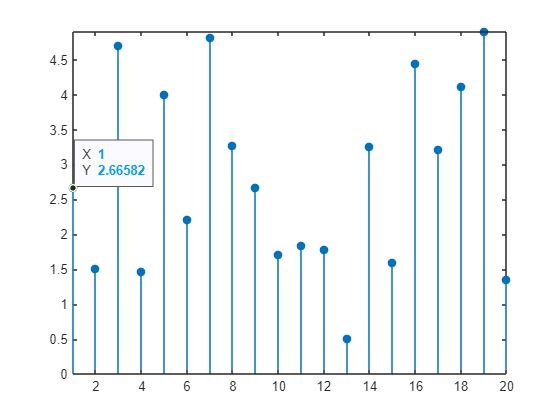


% Chart the timings
lChartTimings(timings)

#### Helper functions

function [quiztime, failed] = lGiveQuiz(graderange,q)
% GRADERANGE is a 1x2 vector [low high] range of grades
% Q is a handle to a parallel DataQueue

% Each student takes a random amount of time to take the quiz
% (up to 5 "minutes")
quiztime = 5 * rand;
pause(quiztime)

% Generate a uniformly distributed pseudorandom score in the grade range
% (e.g., 49 to 100)
grade = randi(graderange);
failed = grade<70;

% Send the timing back to record the timing while the remaining students
% finish their work
% TODO: Call send() to pass the grade (grade) of the quiz back to the
% MATLAB client
send(q,grade)

end

function lPostGrade(grade)

fprintf("Grade: %d\n", grade)

end

function lChartTimings(timings)
% Create stem plot of timings

h = stem(timings,"filled");
axis tight

% Display data tips to show timings
datatip(h);

end

% Turn off Code Analyzer warnings
%#ok<*DEFNU>
%#ok<*INUSD>

*Copyright 2024 The MathWorks, Inc.*